mu=(1+1i)/2;
u=[-mu,-mu;mu',-mu'];

ugate=qclab.QCircuit(1);
ugate.push_back(qclab.qgates.RotationX(0,pi/2));
ugate.push_back(qclab.qgates.RotationY(0,-pi/2));
ugate.push_back(qclab.qgates.RotationZ(0,pi));
norm(ugate.matrix-u)

ans = 2.0770e-16

u2=mpower(u,2);
ugatesquared=qclab.QCircuit(1);
ugatesquared.push_back(qclab.qgates.RotationZ(0,-3*pi/2));
ugatesquared.push_back(qclab.qgates.RotationY(0,pi/2));
norm(ugatesquared.matrix-u2)

ans = 1.5701e-16



Q8FFT=qclab.QCircuit(3)

Q8FFT = QCircuit with properties 

     nbQubits: 3
    nbObjects: 0
       offset: 0


Q8FFT.push_back(qclab.qgates.Hadamard(0))
Q8FFT.push_back(qclab.qgates.CPhase(1,0,pi/2))
Q8FFT.push_back(qclab.qgates.Hadamard(1))
Q8FFT.push_back(qclab.qgates.MCX([0,2],1))
Q8FFT.push_back(qclab.qgates.Hadamard(2))
Q8FFT.push_back(qclab.qgates.SWAP(0,1))

XY=qclab.qgates.PauliX.matrix*qclab.qgates.PauliY.matrix

XY =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


Q8FFT.push_back(qclab.qgates.MCMatrixGate(2,0,XY))
Q8FFT.push_back(qclab.qgates.MCMatrixGate([2,1],0,XY,[1,0]))
Q8FFT.push_back(qclab.qgates.Hadamard(2))
Q8FFT.push_back(qclab.qgates.Hadamard(0))
Q8FFT.push_back(qclab.qgates.MCMatrixGate(2,0,XY))
Q8FFT.push_back(qclab.qgates.MCMatrixGate([2,1],0,XY,[1,0]))
Q8FFT.push_back(qclab.qgates.Hadamard(0))
Q8FFT.draw()

     ┏━┓ ┏━┓           ┏━━━┓ ┏━━━┓ ┏━┓ ┏━━━┓ ┏━━━┓ ┏━┓ 
q0: ━┫H┣━┫P┣━━━━━●━⨯━━━┫ U ┣━┫ U ┣━┫H┣━┫ U ┣━┫ U ┣━┫H┣━
     ┗━┛ ┗┳┛     ┃ ┃   ┗━┳━┛ ┗━┳━┛ ┗━┛ ┗━┳━┛ ┗━┳━┛ ┗━┛ 
          ┃  ┏━┓ ┃ ┃     ┃     ┃         ┃     ┃       
q1: ━━━━━━●━━┫H┣━⊕━⨯━━━━━╋━━━━━○━━━━━━━━━╋━━━━━○━━━━━━━
             ┗━┛ ┃       ┃     ┃         ┃     ┃       
                 ┃ ┏━┓   ┃     ┃   ┏━┓   ┃     ┃       
q2: ━━━━━━━━━━━━━●━┫H┣━━━●━━━━━●━━━┫H┣━━━●━━━━━●━━━━━━━
                   ┗━┛             ┗━┛                 


final1=Q8FFT.matrix

final1 =    0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i
  -0.5000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i
   0.2500 + 0.2500i   0.2500 - 0.2500i  -0.2500 + 0.2500i  -0.2500 - 0.2500i  -0.2500 - 0.2500i  -0.2500 + 0.2500i   0.2500 - 0.2500i   0.2500 + 0.2500i
  -0.2500 + 0.2500i   0.2500 + 0.2500i   0.2500 + 0.2500i  -0.2500 + 0.2500i   0.2500 - 0.2500i  -0.2500 - 0.2500i  -0.2500 - 0.2500i   0.2500 - 0.2500i
   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i
  -0.5000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i
   0.2500 - 0.2500i   0.2500 + 0.2500i  -0.2500 - 0.2500i  -0.2500 + 0.25

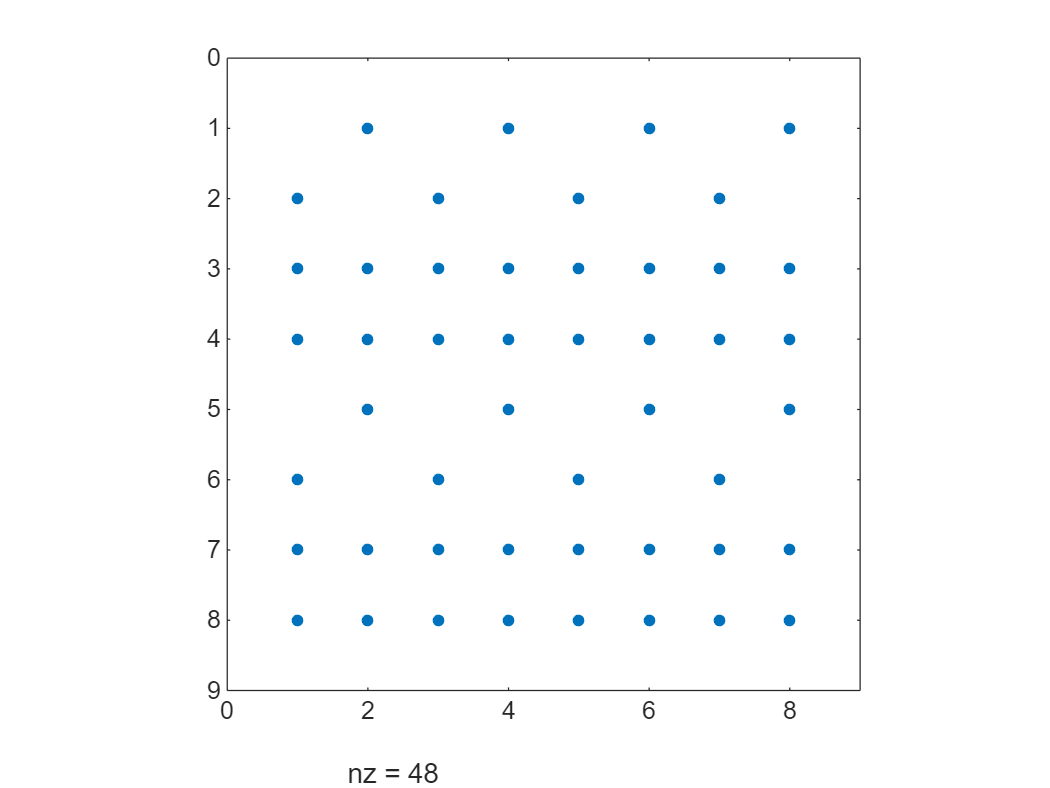

spy(final1)



Q8FFT=qclab.QCircuit(3)

Q8FFT = QCircuit with properties 

     nbQubits: 3
    nbObjects: 0
       offset: 0


Q8FFT.push_back(qclab.qgates.Hadamard(2))
Q8FFT.push_back(qclab.qgates.CPhase(2,1,pi/2))
Q8FFT.push_back(qclab.qgates.Hadamard(1))
Q8FFT.push_back(qclab.qgates.MCX([0,2],1))
Q8FFT.push_back(qclab.qgates.Hadamard(0))
Q8FFT.push_back(qclab.qgates.SWAP(2,1))

XY=qclab.qgates.PauliX.matrix*qclab.qgates.PauliY.matrix

XY =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


Q8FFT.push_back(qclab.qgates.MCMatrixGate(0,2,XY))
Q8FFT.push_back(qclab.qgates.MCMatrixGate([0,1],2,XY,[1,0]))
Q8FFT.push_back(qclab.qgates.Hadamard(0))
Q8FFT.push_back(qclab.qgates.Hadamard(2))
Q8FFT.push_back(qclab.qgates.MCMatrixGate(0,2,XY))
Q8FFT.push_back(qclab.qgates.MCMatrixGate([0,1],2,XY,[1,0]))
Q8FFT.push_back(qclab.qgates.Hadamard(2))
Q8FFT.draw()

                   ┏━┓             ┏━┓                 
q0: ━━━━━━━━━━━━━●━┫H┣━━━●━━━━━●━━━┫H┣━━━●━━━━━●━━━━━━━
                 ┃ ┗━┛   ┃     ┃   ┗━┛   ┃     ┃       
         ┏━┓ ┏━┓ ┃       ┃     ┃         ┃     ┃       
q1: ━━━━━┫P┣━┫H┣━⊕━⨯━━━━━╋━━━━━○━━━━━━━━━╋━━━━━○━━━━━━━
         ┗┳┛ ┗━┛ ┃ ┃     ┃     ┃         ┃     ┃       
     ┏━┓  ┃      ┃ ┃   ┏━┻━┓ ┏━┻━┓ ┏━┓ ┏━┻━┓ ┏━┻━┓ ┏━┓ 
q2: ━┫H┣━━●━━━━━━●━⨯━━━┫ U ┣━┫ U ┣━┫H┣━┫ U ┣━┫ U ┣━┫H┣━
     ┗━┛               ┗━━━┛ ┗━━━┛ ┗━┛ ┗━━━┛ ┗━━━┛ ┗━┛ 


final=Q8FFT.matrix

final =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i
   0.2500 + 0.2500i  -0.2500 - 0.2500i  -0.2500 + 0.2500i   0.2500 - 0.2500i   0.2500 - 0.2500i  -0.2500 + 0.2500i  -0.2500 - 0.2500i   0.2500 + 0.2500i
   0.2500 - 0.2500i  -0.2500 + 0.2500i  -0.2500 - 0.2500i   0.2500 + 0.2500i   0.2500 + 0.2500i  -0.2500 - 0.2500i  -0.2500 + 0.2500i   0.2500 - 0.2500i
  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.0000i  -0.5000 + 0.0000i   0.5000 + 0.0000i   0.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.2500 + 0.2500i   0.2500 - 0.2500i   0.2500 + 0.2500i  -0.2500 - 0.250

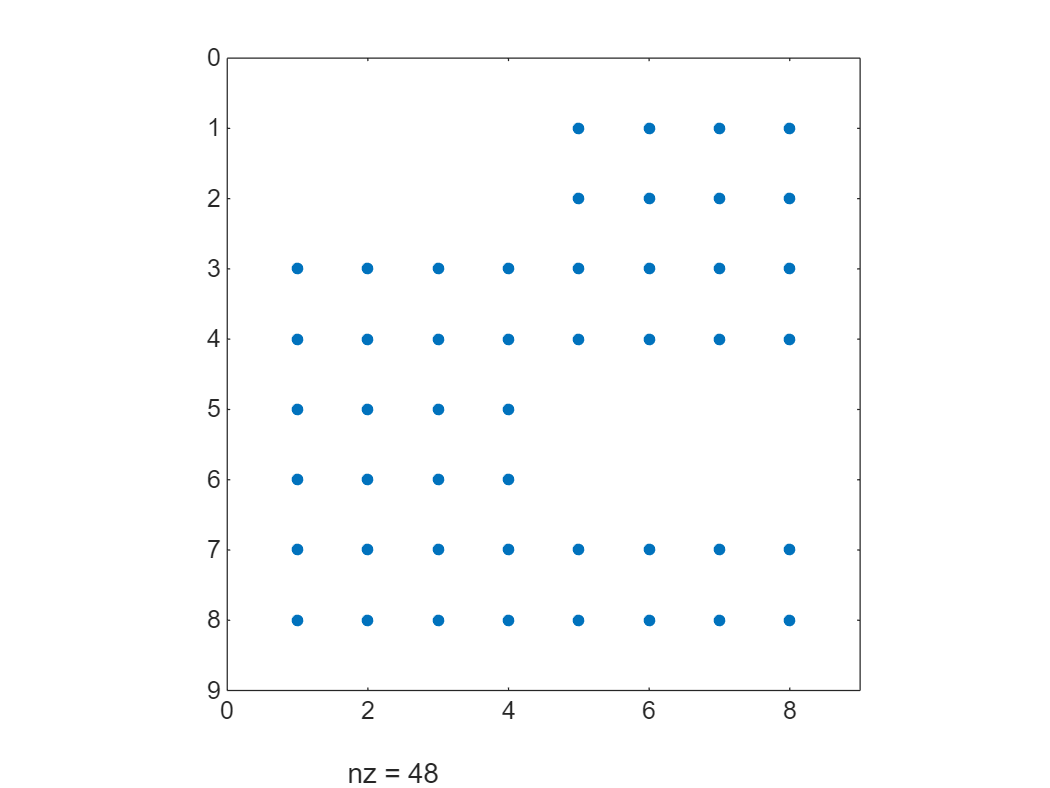

spy(final)

A4=qclab.QCircuit(4);
A4.push_back(qclab.qgates.Hadamard(2))
A4.push_back(qclab.qgates.Hadamard(3))
A4.matrix

ans =     0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000   -0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.5000   -0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000   -0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0
         0         0        

%spy(A4.matrix)
T=qclab.QCircuit(2);
T.push_back(qclab.qgates.CNOT(0,1))
T.push_back(qclab.qgates.CNOT(1,0))
Tmat=T.matrix

Tmat =      1     0     0     0
     0     0     1     0
     0     0     0     1
     0     1     0     0


A4.push_back(qclab.qgates.MCMatrixGate([0,1],[2,3],Tmat,[0,1]))


T2=qclab.QCircuit(2);
T2.push_back(qclab.qgates.CNOT(1,0))
T2.push_back(qclab.qgates.CNOT(0,1))
Tmat2=T2.matrix

Tmat2 =      1     0     0     0
     0     0     0     1
     0     1     0     0
     0     0     1     0


A4.push_back(qclab.qgates.MCMatrixGate([0,1],[2,3],Tmat2,[1,0]))
A4.matrix

ans =     0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000   -0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.5000   -0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000    0.5000   -0.5000   -0.5000         0         0         0         0         0         0         0         0
         0         0        

res=A4.matrix

res =     0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.5000    0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000    0.5000   -0.5000   -0.5000         0         0         0         0         0         0         0         0         0         0         0         0
    0.5000   -0.5000   -0.5000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0
         0         0         0         0    0.5000    0.5000   -0.5000   -0.5000         0         0         0         0         0         0         0         0
         0         0        

spy(res)

A4.draw

                     
q0: ━━━━━━━○━━━━━●━━━
           ┃     ┃   
           ┃     ┃   
q1: ━━━━━━━●━━━━━○━━━
           ┃     ┃   
     ┏━┓ ┏━┻━┓ ┏━┻━┓ 
q2: ━┫H┣━┫   ┣━┫   ┣━
     ┗━┛ ┃ U ┃ ┃ U ┃ 
     ┏━┓ ┃   ┃ ┃   ┃ 
q3: ━┫H┣━┫   ┣━┫   ┣━
     ┗━┛ ┗━━━┛ ┗━━━┛ 



omega = exp(2i * pi / 3);

% Define the 3x3 DFT matrix F3
F3 = (1/sqrt(3)) * [1,       1,       1;
                    1,  omega, omega^2;
                    1, omega^2,  omega];

% Embed F3 into a 4x4 unitary matrix U
DFT3 = eye(4);        % Start with identity
DFT3(1:3, 1:3) = F3;  % Replace top-left 3x3 block with F3
H3=qclab.qgates.MatrixGate([0,1],DFT3);

A4.push_back(H3)
A4.draw()

                     ┏━━━┓ 
q0: ━━━━━━━○━━━━━●━━━┫   ┣━
           ┃     ┃   ┃ U ┃ 
           ┃     ┃   ┃   ┃ 
q1: ━━━━━━━●━━━━━○━━━┫   ┣━
           ┃     ┃   ┗━━━┛ 
     ┏━┓ ┏━┻━┓ ┏━┻━┓       
q2: ━┫H┣━┫   ┣━┫   ┣━━━━━━━
     ┗━┛ ┃ U ┃ ┃ U ┃       
     ┏━┓ ┃   ┃ ┃   ┃       
q3: ━┫H┣━┫   ┣━┫   ┣━━━━━━━
     ┗━┛ ┗━━━┛ ┗━━━┛       


tmp=A4.matrix()

tmp =    0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i  -0.2887 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.2887 + 0.0000i  -0.2887 + 0.0000i  -0.2887 + 0.0000i   0.2887 + 0.0000i   

tmp2=tmp(1:12,1:12);